## Generate 4-QAM Image Data

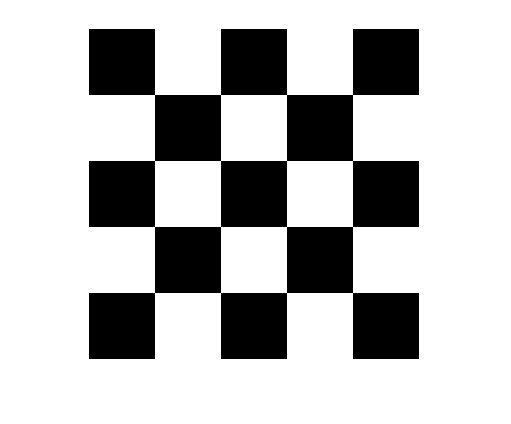

im = imread('data\checkerboard.jpg');
imBW = im2bw(im,.7);
figure;
imshow(imBW)

## Generate TX Data

clear;
hamming_on = 1;
picture = 'checkerboard';
%generate start sequence
input_image = strcat('data\',picture,'.jpg');
pilot_seq_len = 32; % length of known pilot sequence
ending_seq_len = 32;
Fs = 2000000; % sampling frequency

%generate RRC Pulse
T = 50; % Symbol Period
span = 20;
rolloff = 0.5;
rrc = rcosdesign(rolloff,span,T, 'sqrt');   % creates a root-raised cosine 

[imBW,dataQ,data] = image_to_data(input_image,hamming_on);

if hamming_on
    txname = strcat('data\', picture, '_ham.dat');
else
    txname = strcat('data\', picture, '.dat');
end
txname

txname = 'data\checkerboard_ham.dat'

build_tx_file(txname, dataQ, pilot_seq_len, ending_seq_len, rrc, T)

## Decode RX Data

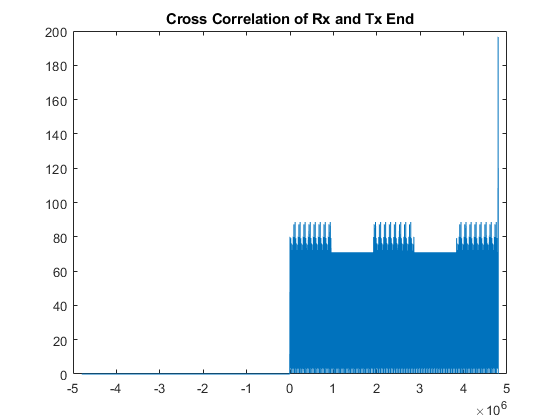

startPos = 0

endPos = 4796300

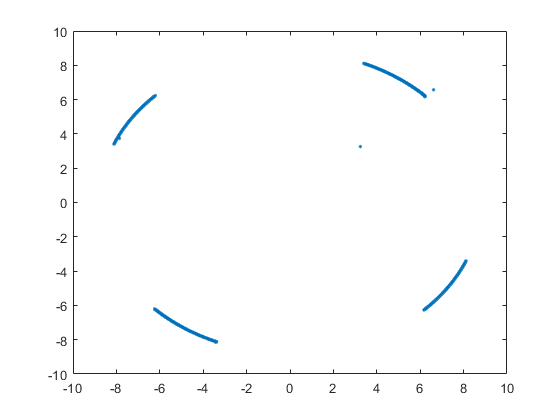

ans = 95894

ans = 95894

txname='data\checkerboard_ham.dat';
rxname = 'data\checkerboard_ham.dat';
figure;
[rxQ, errRate] = qpsk(txname, rxname, T, 2000000);   

errRate

errRate = 0

## Printing Image

rxQ = sign(real(rxQ)) + 1i*sign(imag(rxQ));
rxBinary = decodeQam(rxQ);

if hamming_on
    rxBinary = errorCorrect(rxBinary);
end
 
rows = bi2de(rxBinary(1:16),'left-msb');
cols = bi2de(rxBinary(17:32),'left-msb');

if mod(rows*cols,2) ~= 0
    dataRx = rxBinary(33:end-1);
else
    dataRx = rxBinary(33:end);
end
compute_qpsk_error(data,dataRx)

ans = 0

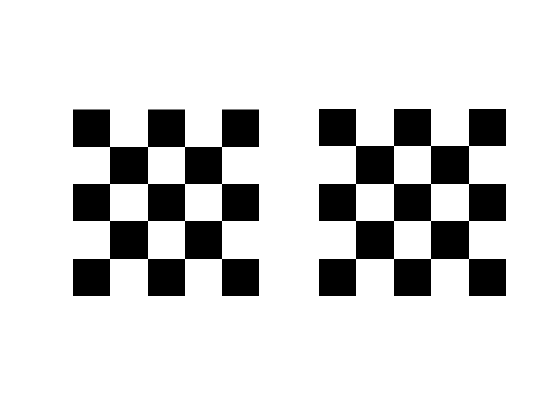

rxIm = reshape(dataRx, rows, []);
figure;
subplot(1,2,1)
imshow(rxIm)
subplot(1,2,2)
imshow(imBW)